**Read the input image**

img = imread('f18.tif');
img = im2double(img); % Convert to double for processing
[M, N] = size(img); % Get image dimensions

**Display the original image**

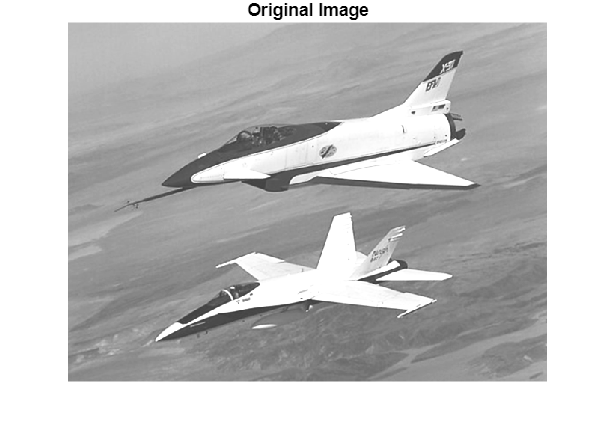

figure;
imshow(img);
title('Original Image', 'FontSize', 14);

**Create frequency domain coordinates**

[u, v] = meshgrid(-N/2:N/2-1, -M/2:M/2-1);
D = u.^2 + v.^2; % Distance squared for turbulence model

**Perform FFT of the image**

F = fftshift(fft2(img));

**Atmospheric Turbulence Degradation**

k_values = [0.0025, 0.001, 0.00025]; % Different k values
degraded_turbulence = cell(1,3);

for i = 1:3
    k = k_values(i);
    H_turbulence = exp(-k * D); % Turbulence degradation function
    G_turbulence = H_turbulence .* F; % Apply degradation in frequency domain
    degraded_turbulence{i} = abs(ifft2(ifftshift(G_turbulence))); % Inverse FFT
end

**Uniform Linear Motion Blur Degradation**

a = 0.1; b = 0.1; T = 1;
H_motion = (sinc(a * u + b * v) .* exp(-1j * pi * (a * u + b * v) * T));

**Apply motion blur degradation**

G_motion = H_motion .* F;
degraded_motion = abs(ifft2(ifftshift(G_motion))); % Inverse FFT

**Display Results with Fixes**

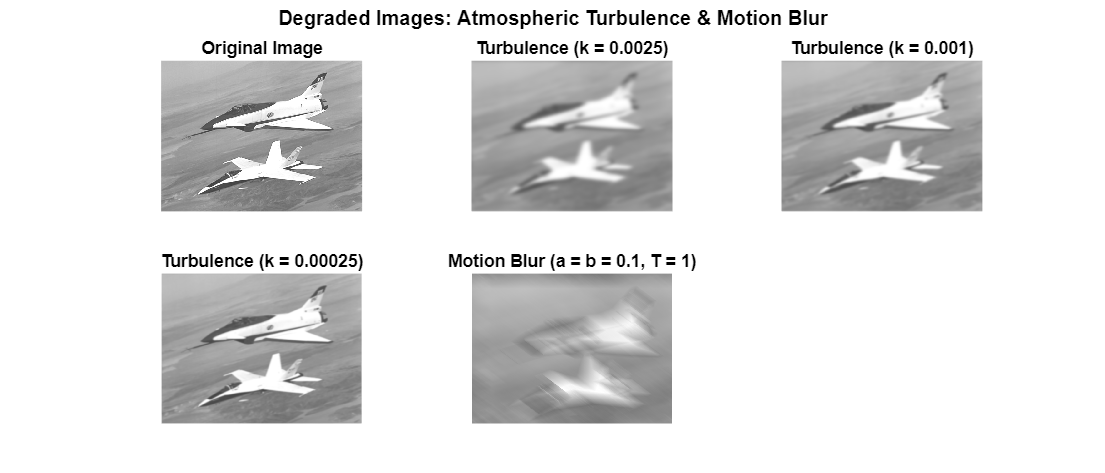

figure;
set(gcf, 'Position', [100, 100, 1400, 600]); % Increase figure size

subplot(2,3,1), imshow(img), title('Original Image', 'FontSize', 14);
subplot(2,3,2), imshow(degraded_turbulence{1}), title('Turbulence (k = 0.0025)', 'FontSize', 14);
subplot(2,3,3), imshow(degraded_turbulence{2}), title('Turbulence (k = 0.001)', 'FontSize', 14);
subplot(2,3,4), imshow(degraded_turbulence{3}), title('Turbulence (k = 0.00025)', 'FontSize', 14);
subplot(2,3,5), imshow(degraded_motion), title('Motion Blur (a = b = 0.1, T = 1)', 'FontSize', 14);

sgtitle('Degraded Images: Atmospheric Turbulence & Motion Blur', 'FontSize', 16, 'FontWeight', 'bold');